%Importing the data
basketball = importfile("C:\Downloads\nba-salaries-prediction-in-20172018-season\basketball.csv", [2, Inf]);
y = table2array(basketball(: , 2));
x = table2array(basketball(:, 7:20));
m=length(y);
y = y./1000000;
combined = [x y];

%Scatter plots and analysis
fprintf('We will now see various scatter plots and their analysis\n');

We will now see various scatter plots and their analysis


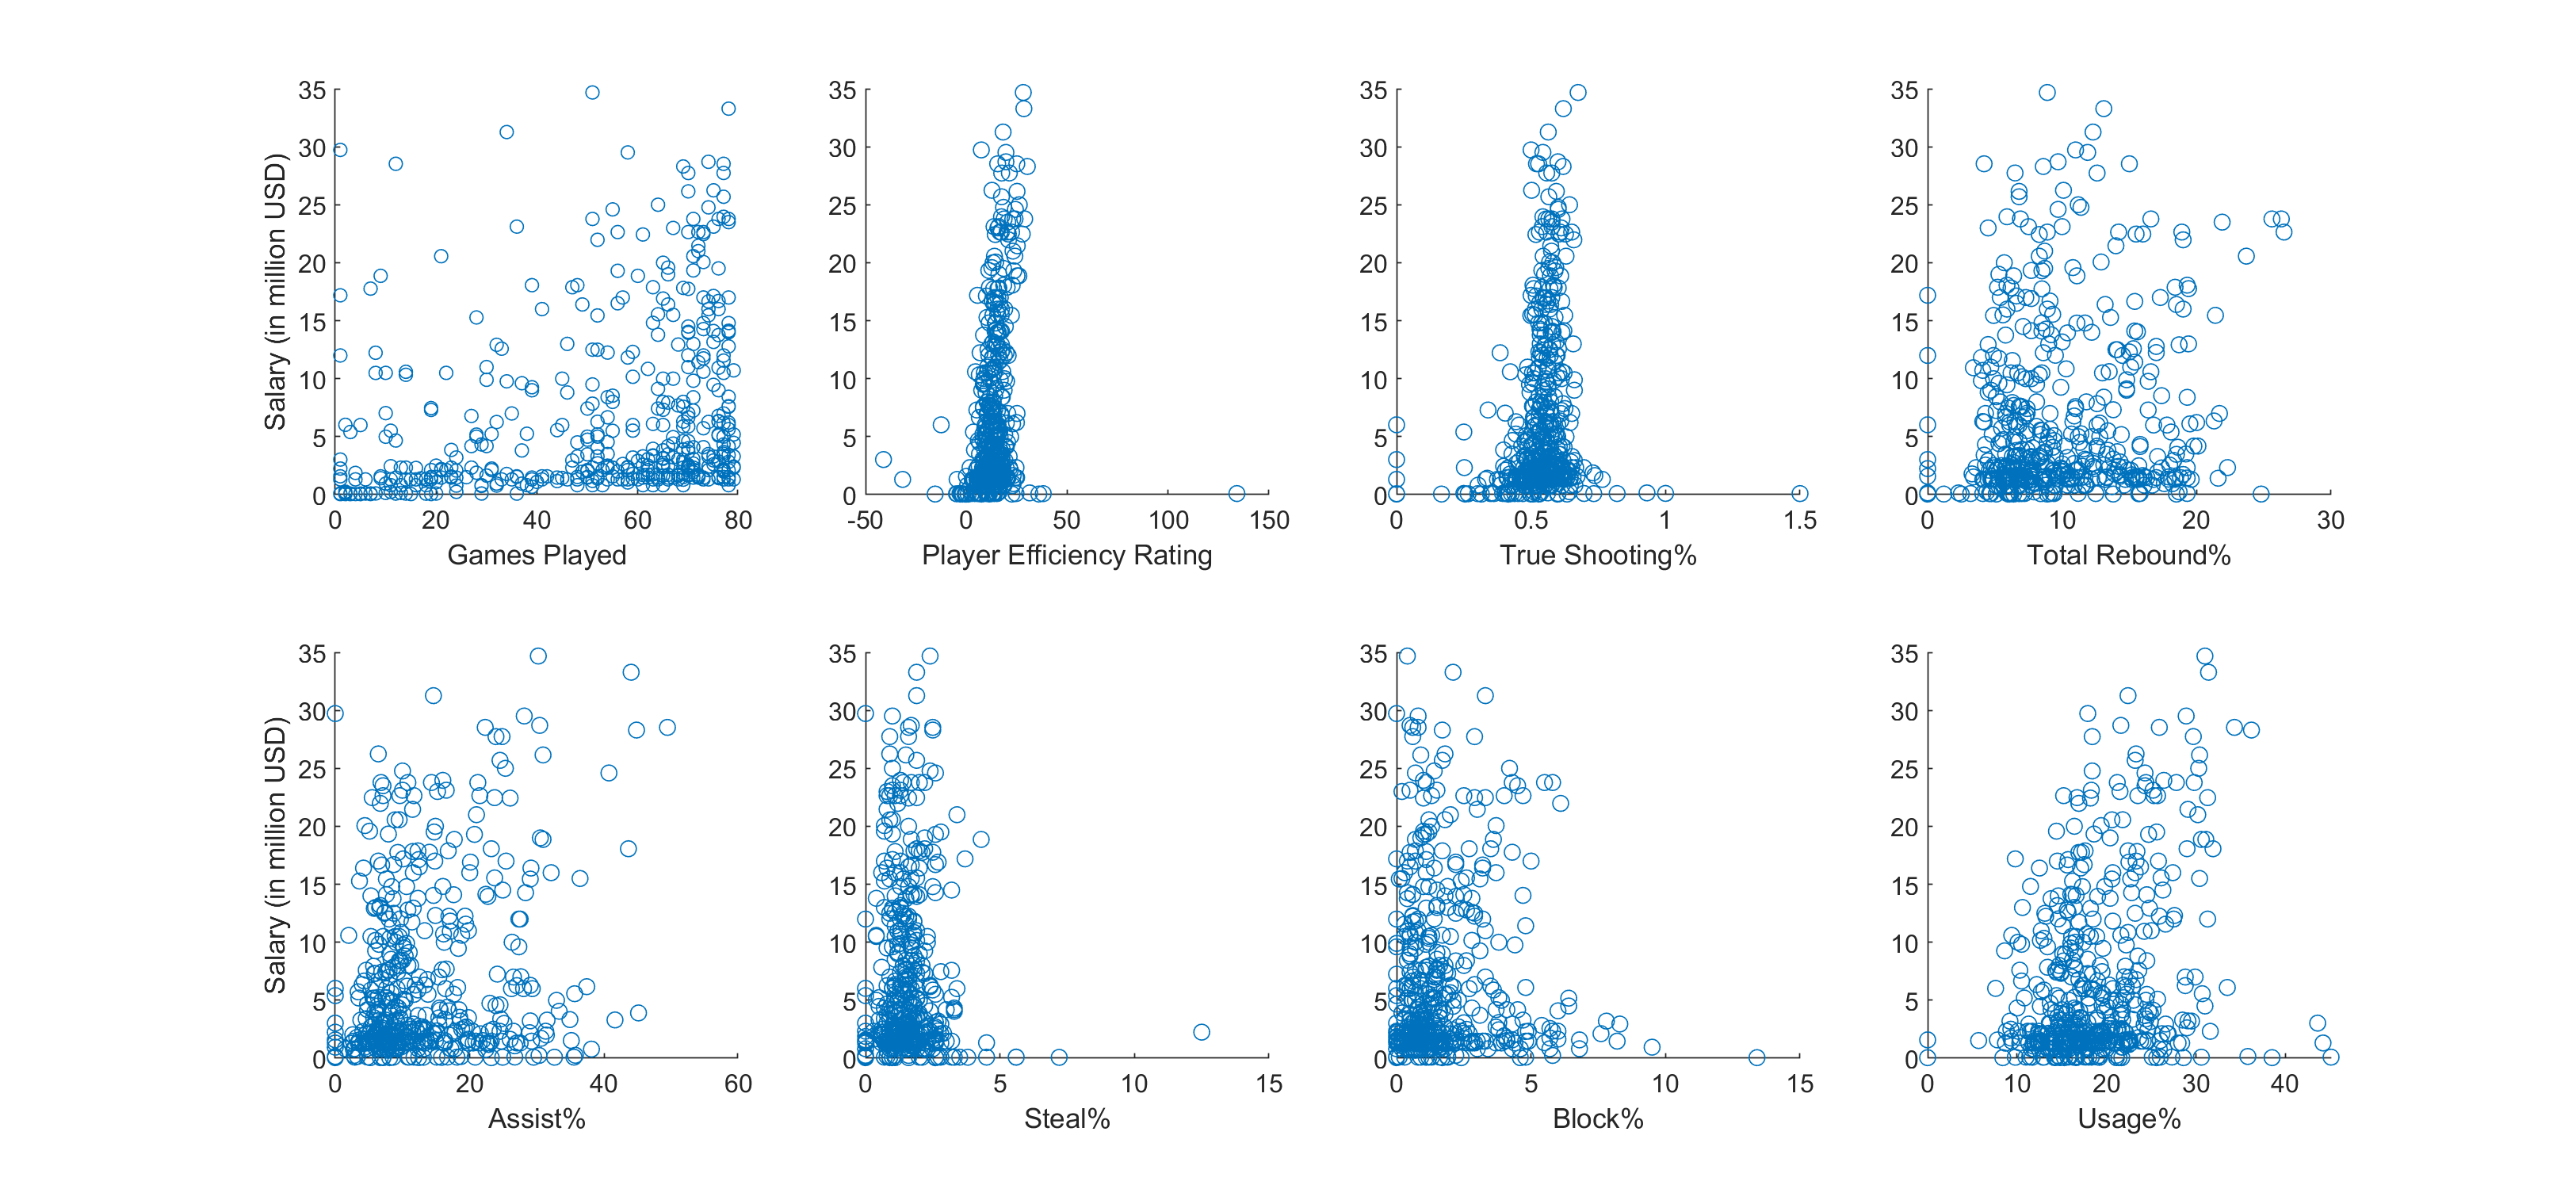


figure(1);
set(gcf, 'Position',  [100, 100, 1300, 600])

subplot(2,4,1);
scatter(x(:,1),y,25);
xlabel('Games Played');
ylabel('Salary (in million USD)');

subplot(2,4,2); 
scatter(x(:,3),y);
PER = (x(:,3));
%hold on;
%mdl = fitlm(x(:,3),y);
%plot(x(:,3), predict(mdl,x(:,3)));
xlabel('Player Efficiency Rating');

subplot(2,4,3); 
scatter(x(:,4),y);
xlabel('True Shooting%');

subplot(2,4,4); 
scatter(x(:,9),y);
xlabel('Total Rebound%');

subplot(2,4,5); 
scatter(x(:,10),y);
xlabel('Assist%');
ylabel('Salary (in million USD)');

subplot(2,4,6); 
scatter(x(:,11),y);
xlabel('Steal%');

subplot(2,4,7); 
scatter(x(:,12),y);
xlabel('Block%');

subplot(2,4,8); 
scatter(x(:,14),y);
xlabel('Usage%');


fprintf('From the above scatter plots we conclude that there is a definite linear relation between\n');

From the above scatter plots we conclude that there is a definite linear relation between


fprintf('player efficiency raing and salary. There also seems to be a rough linear relation \n');

player efficiency raing and salary. There also seems to be a rough linear relation 


fprintf('between player salary with shooting and steal percentages. \n\n');

between player salary with shooting and steal percentages. 



%Draft pick vs salary and PER
fprintf('\n\n\nNow for a question...Does the past affect the present? We will see how draft pick affected player salary\n');




Now for a question...Does the past affect the present? We will see how draft pick affected player salary


fprintf('and efficiency (PER)');

and efficiency (PER)

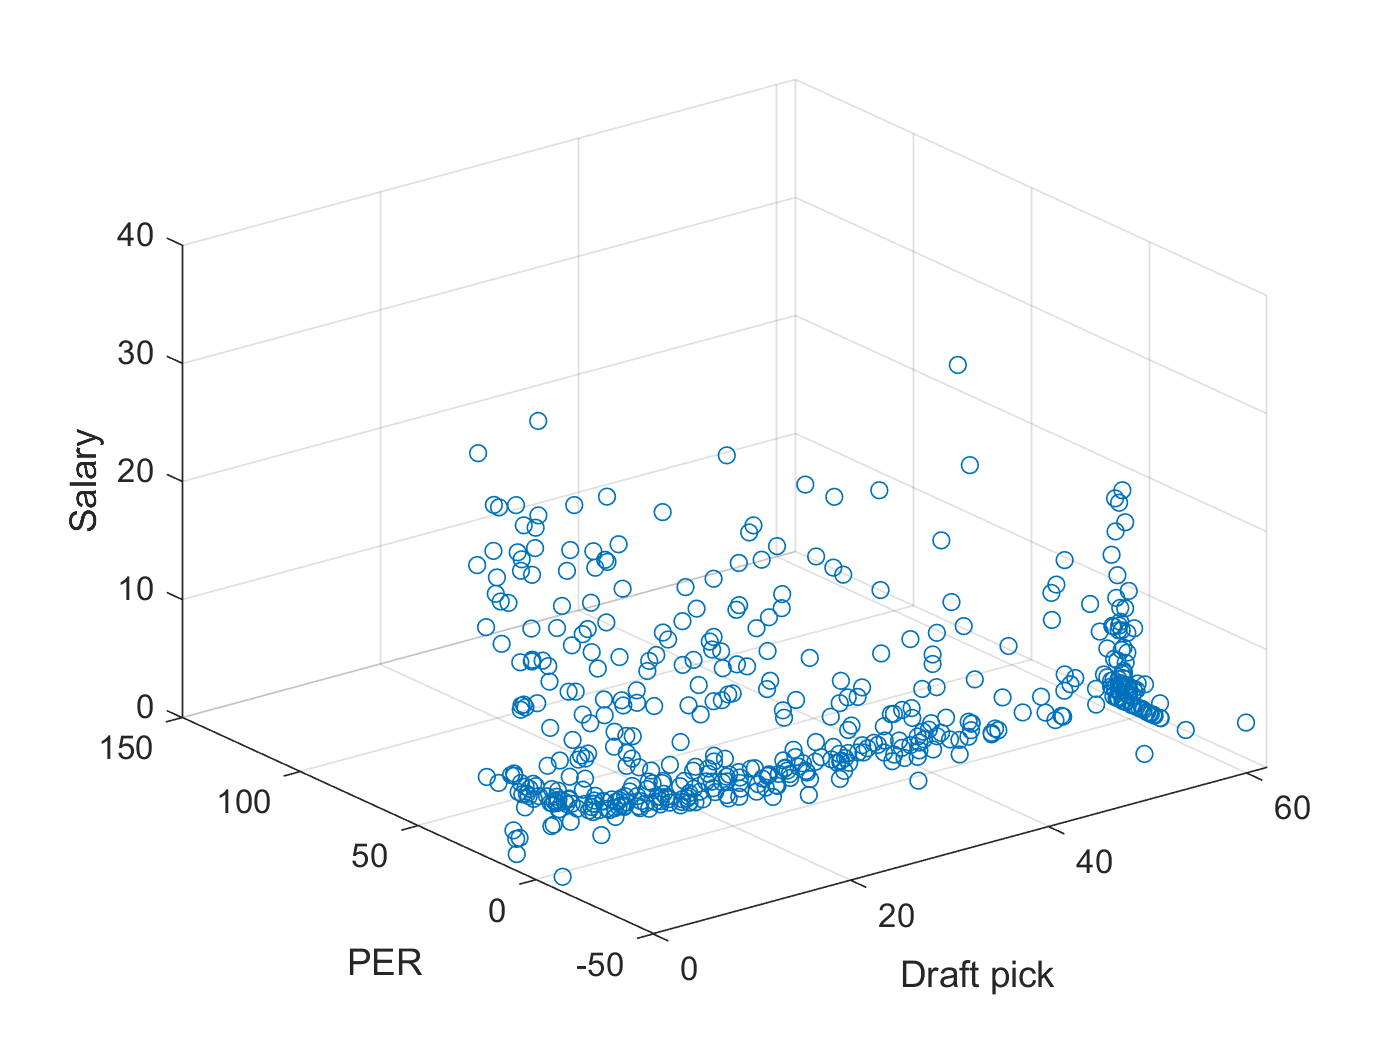

draft_pick = table2array(basketball(:,4));
figure(4);
sz = 25;
scatter3(draft_pick,PER,y,sz);
xlabel('Draft pick');
ylabel('PER');
zlabel('Salary');

fprintf('Although a better draft pick indicates a somewhat better salary, quite a number of instances are seen \n');

Although a better draft pick indicates a somewhat better salary, quite a number of instances are seen 


fprintf('where bad draft picks are getting good salaries over 10 million USD and better PER, while better draft picks \n');

where bad draft picks are getting good salaries over 10 million USD and better PER, while better draft picks 


fprintf('getting less. So a player who was relatively good in college need not be so in the NBA.\n\n\n\n ');

getting less. So a player who was relatively good in college need not be so in the NBA.



 

%Player salary with age
fprintf('Now to see how players do with age\n\n');

Now to see how players do with age



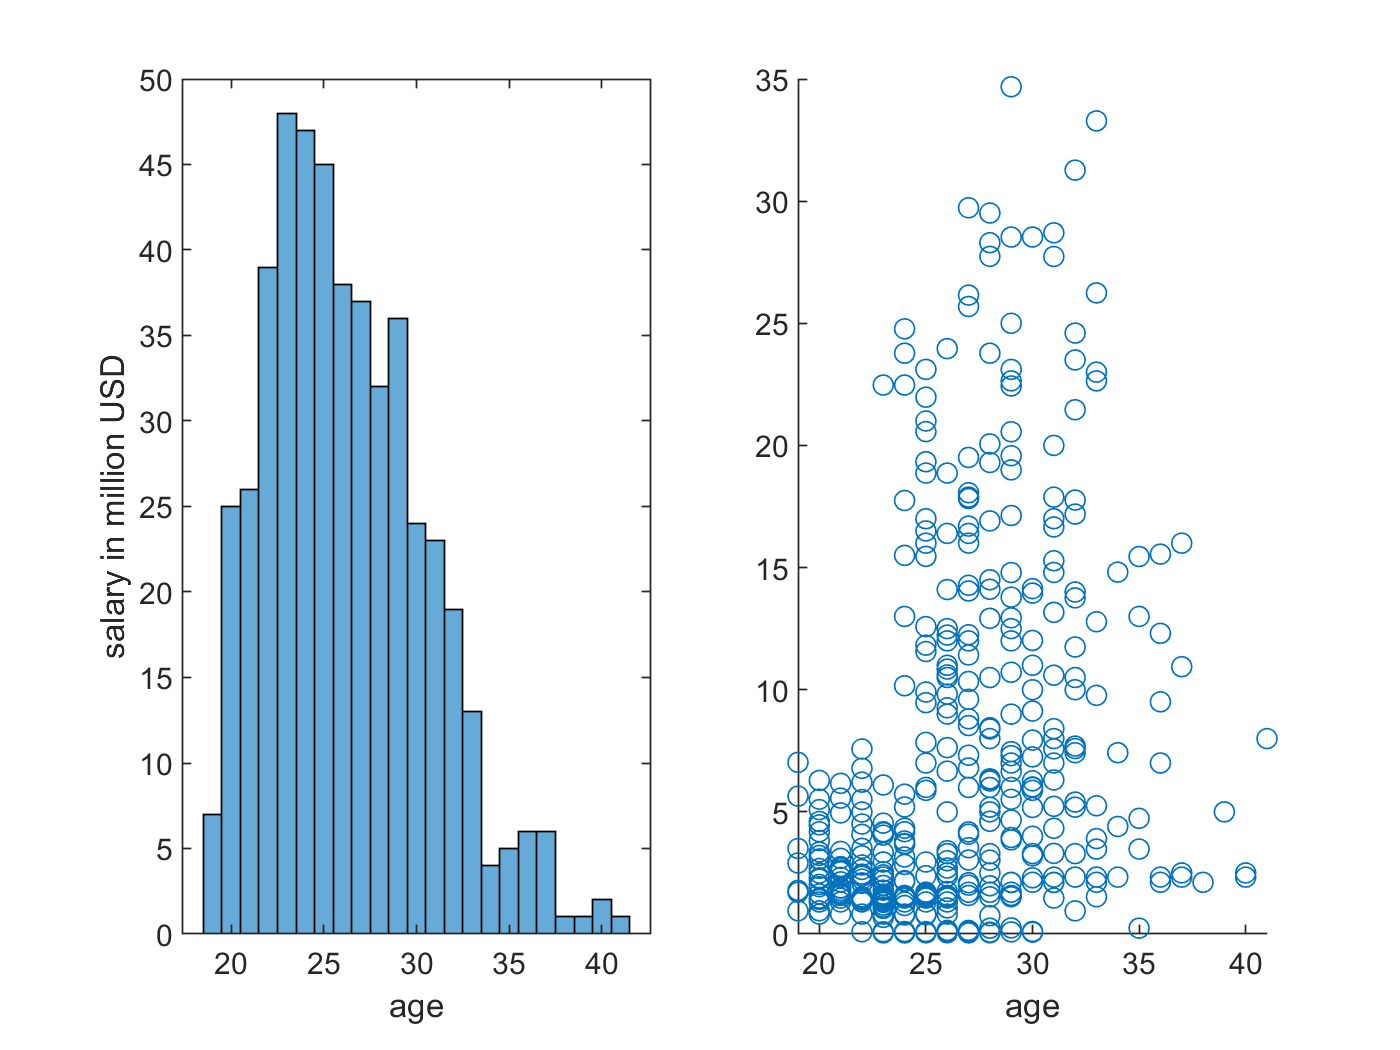

figure(2);
subplot(1,2,1);
histogram(age);
xlabel('age');
ylabel('salary in million USD');

subplot(1,2,2);
scatter(age,y);
xlabel('age');


fprintf('We note that although most players in the NBA are around the age of 25 years old players between the\n');

We note that although most players in the NBA are around the age of 25 years old players between the


fprintf('age of 28 and 33 have higher salaries than others. We can conclude that most players reach their\n');

age of 28 and 33 have higher salaries than others. We can conclude that most players reach their


fprintf('prime at this age and hence are paid higher\n\n\n\n\n\n\n\n');

prime at this age and hence are paid higher









%Age vs accuracy
figure(3);
set(gcf, 'Position',  [100, 100, 900, 600])
scatter(age,x(:,5));
xlabel('age');
ylabel('free throw rate');

xlim([15.0 45.0])
ylim([0.000 1.000])

fprintf('One could expect for 3 point accuracy to increase with age, however no such correlation is seen\n');

One could expect for 3 point accuracy to increase with age, however no such correlation is seen


fprintf('We can say that the 3 pointer is a pretty popular shot in the NBA. \n\n');

We can say that the 3 pointer is a pretty popular shot in the NBA. 



%Training a model for the given data and calculating RMSE
[trainedModel, RMSE] = RegressionModel(combined);
fprintf('RMSE of the given model is %f\n' ,  RMSE);

RMSE of the given model is 5.995387


yPred = trainedModel.predictFcn(x);

%Using regression model to predict salary 
choice = ' ';
prompt = 'Let us now predict the salary of a player with given attributes Type ''y'' to proceed,''n'' to skip.\n';
choice = input (prompt);

while choice=='y'
    
    fprintf('Enter the following attributes in given order\n ');
    fprintf('G	MP	PER	 TS%%	3PAr	FTr	ORB%%	DRB%%	TRB%%	AST%%	STL%%	BLK%%	TOV%%	USG%% \n\n');
    predict_case = zeros(14);
    limit=14;
    n=1;
    while n<=limit
      predict_case(n)=input(' ');
      n=n+1;
    end
    salary_predicted = trainedModel.predictFcn(predict_case);
    fprintf('Predicted salary of the player in million USD is %d\n' , salary_predicted);
    choice = input('again? ''y''/''n''  \n');
end;